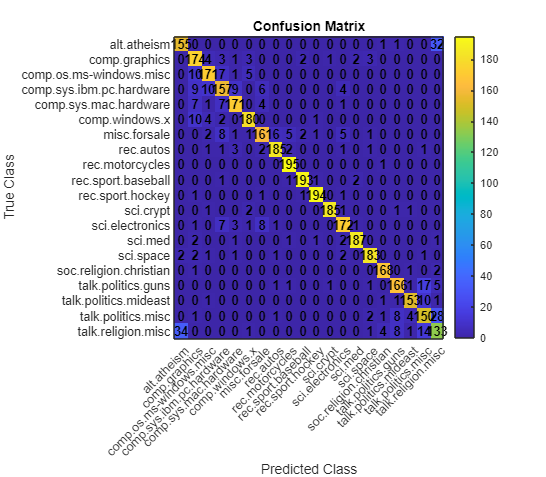

% Plot_Confusion_Matrix.mlx

% Read in data from CSV
C = readcell("confusion_matrix_all.csv");

% Extract labels
trueLabels = string(C(2:end,1));
predictedLabels = string(C(1,2:end));
    
% Extract numeric data
data = cell2mat( C(2:end,2:end) );
n = size(data,1);
    
% Plot the matrix
figure('Position',[100 100 800 700]);
imagesc(data);
colormap("parula");
colorbar;
title('Confusion Matrix','FontWeight','bold');
xlabel('Predicted Class');
ylabel('True Class');
    
% Add ticks and labels
ax = gca;
ax.XTick = 1:n;
ax.YTick = 1:n;
ax.XTickLabel = predictedLabels;
ax.YTickLabel = trueLabels;
ax.XTickLabelRotation = 45;
ax.TickLength = [0 0];
    
% Overlay count text
textStrings = num2str(data(:),'%d'); 
textStrings = strtrim(cellstr(textStrings));
[xGrid, yGrid] = meshgrid(1:n);
hStrings = text(xGrid(:), yGrid(:), textStrings(:), 'HorizontalAlignment','center', 'FontWeight','bold');

set(hStrings(k),'Color','black');
